**Glossary Network Semantic Analysis**				

The *glossary* network is a semantic network, where nodes represent concepts in graph theory and oriented edges represent semantic dependencies. Arguably, some concepts are more “fundamental” while others are more “complex”. After extracting the largest (weakly) connected component, use in/out-degrees, PageRank, Katz indices and/or HITS scores to detect “fundamental” and “complex” concepts. 	

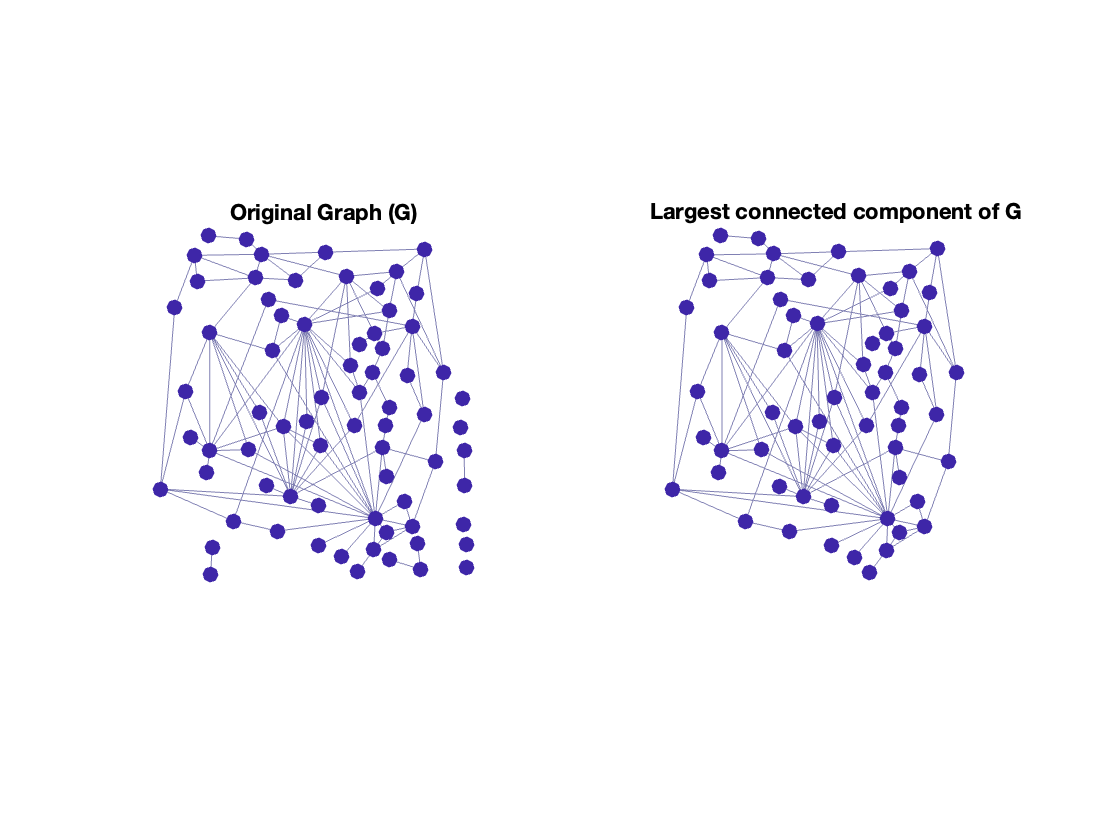

clear;
close all;

load glossary.mat

[nComponents,sizes,membership] = F_connected(A);

main_component_nodes = find(membership == 1);

B = A(main_component_nodes, main_component_nodes);

xy_B = xy(main_component_nodes,:);
word_B = word(main_component_nodes);

figure()
tiledlayout(1,2);
nexttile
F_gplot(A,xy);
title('Original Graph (G)');
daspect([1 1 1]);

nexttile
F_gplot(B,xy_B);
title('Largest connected component of G');
daspect([1 1 1]);

clear G;
clear A;

**Calculating centrality indices scores and extracting the nodes with top 5 centrality scores**

GB = digraph(B, word_B);
indeg_A = indegree(GB);
indeg_B = indegree(GB);
outdeg_B = outdegree(GB);
pagerank = centrality(GB,'pagerank');
hub_matlab = centrality(GB, 'hubs');
auth_matlab = centrality(GB, 'authorities');
[h,a] = F_HITS(B);

Power Method converged after 11 iterations


k = F_KATZ(B);

GB.Nodes.InDegree = indeg_B;
GB.Nodes.OutDegree = outdeg_B;
GB.Nodes.PageRank = pagerank;
GB.Nodes.Hub = h;
GB.Nodes.Auth = a;
GB.Nodes.Hub_matlab = hub_matlab;
GB.Nodes.Auth_matlab = auth_matlab;
GB.Nodes.KATZ = k;

GB_nodes_scores = sortrows(GB.Nodes, 2, 'descend')

GB_nodes_scores = 60×9 table
             Name              InDegree    OutDegree    PageRank       Hub          Auth       Hub_matlab    Auth_matlab      KATZ  
    _______________________    ________    _________    ________    __________    _________    __________    ___________    ________

    {'Vertex'             }       17           2         0.10941       0.11241      0.58427      0.020686       0.22088      0.46146
    {'Graph'              }       16           0         0.12269             0      0.46902             0       0.21366      0.65281
    {'Edge'               }       11           2        0.087065       0.16087      0.40714      0.029608       0.13826      0.30705

[largest_indeg, largest_indeg_index] = maxk(table2array(GB.Nodes(:,2)),5);
[largest_outdeg, largest_outdeg_index] = maxk(table2array(GB.Nodes(:,3)),5);
[largest_pagerank, largest_pagerank_index] = maxk(table2array(GB.Nodes(:,4)),5);
[largest_hub, largest_hub_index] = maxk(table2array(GB.Nodes(:,5)),5);
[largest_auth, largest_auth_index] = maxk(table2array(GB.Nodes(:,6)),5);
[largest_hub_matlab, largest_hub_matlab_index] = maxk(table2array(GB.Nodes(:,7)),5);
[largest_auth_matlab, largest_auth_matlab_index] = maxk(table2array(GB.Nodes(:,8)),5);
[largest_katz, largest_katz_index] = maxk(table2array(GB.Nodes(:,9)),5);
largest_indeg_arguments = GB.Nodes(largest_indeg_index,:)

largest_indeg_arguments = 5×9 table
       Name       InDegree    OutDegree    PageRank      Hub         Auth      Hub_matlab    Auth_matlab     KATZ  
    __________    ________    _________    ________    ________    ________    __________    ___________    _______

    {'Vertex'}       17           2         0.10941     0.11241     0.58427     0.020686       0.22088      0.46146
    {'Graph' }       16           0         0.12269           0     0.46902            0       0.21366      0.65281
    {'Edge'  }       11           2        0.087065     0.16087     0.40714     0.029608       0.13826      0.30705
    {'Arc'   }        8           1        0.060106    0.070257     0.29621  

largest_outdeg_arguments = GB.Nodes(largest_outdeg_index,:)

largest_outdeg_arguments = 5×9 table
           Name            InDegree    OutDegree    PageRank       Hub        Auth      Hub_matlab    Auth_matlab      KATZ  
    ___________________    ________    _________    _________    _______    ________    __________    ___________    ________

    {'Loop'           }       1            5        0.0064735    0.36847    0.080589     0.067807      0.020291      0.010649
    {'Bipartite Graph'}       0            4        0.0053393    0.31221           0     0.057447             0             0
    {'Condensed Graph'}       0            4        0.0053393    0.30137           0     0.055452             0             0
    {'Forest'         }   

largest_pagerank_arguments = GB.Nodes(largest_pagerank_index,:)

largest_pagerank_arguments = 5×9 table
       Name       InDegree    OutDegree    PageRank      Hub         Auth      Hub_matlab    Auth_matlab     KATZ  
    __________    ________    _________    ________    ________    ________    __________    ___________    _______

    {'Graph' }       16           0         0.12269           0     0.46902            0       0.21366      0.65281
    {'Vertex'}       17           2         0.10941     0.11241     0.58427     0.020686       0.22088      0.46146
    {'Edge'  }       11           2        0.087065     0.16087     0.40714     0.029608       0.13826      0.30705
    {'Arc'   }        8           1        0.060106    0.070257     0.2962

largest_hub_arguments = GB.Nodes(largest_hub_index,:)

largest_hub_arguments = 5×9 table
           Name            InDegree    OutDegree    PageRank       Hub        Auth      Hub_matlab    Auth_matlab      KATZ  
    ___________________    ________    _________    _________    _______    ________    __________    ___________    ________

    {'Loop'           }       1            5        0.0064735    0.36847    0.080589     0.067807       0.020291     0.010649
    {'Bipartite Graph'}       0            4        0.0053393    0.31221           0     0.057447              0            0
    {'Condensed Graph'}       0            4        0.0053393    0.30137           0     0.055452              0            0
    {'Digraph'        }      

largest_auth_arguments = GB.Nodes(largest_auth_index,:)

largest_auth_arguments = 5×9 table
       Name        InDegree    OutDegree    PageRank      Hub        Auth      Hub_matlab    Auth_matlab      KATZ  
    ___________    ________    _________    ________    ________    _______    __________    ___________    ________

    {'Vertex' }       17           2         0.10941     0.11241    0.58427     0.020686       0.22088       0.46146
    {'Graph'  }       16           0         0.12269           0    0.46902            0       0.21366       0.65281
    {'Edge'   }       11           2        0.087065     0.16087    0.40714     0.029608       0.13826       0.30705
    {'Digraph'}        6           3        0.020807     0.27312     0.30

largest_hub_matlab_arguments = GB.Nodes(largest_hub_matlab_index,:)

largest_hub_matlab_arguments = 5×9 table
           Name            InDegree    OutDegree    PageRank       Hub        Auth      Hub_matlab    Auth_matlab      KATZ  
    ___________________    ________    _________    _________    _______    ________    __________    ___________    ________

    {'Loop'           }       1            5        0.0064735    0.36847    0.080589     0.067807       0.020291     0.010649
    {'Bipartite Graph'}       0            4        0.0053393    0.31221           0     0.057447              0            0
    {'Condensed Graph'}       0            4        0.0053393    0.30137           0     0.055452              0            0
    {'Digraph'        

largest_auth_matlab_arguments = GB.Nodes(largest_auth_matlab_index,:)

largest_auth_matlab_arguments = 5×9 table
       Name        InDegree    OutDegree    PageRank      Hub        Auth      Hub_matlab    Auth_matlab      KATZ  
    ___________    ________    _________    ________    ________    _______    __________    ___________    ________

    {'Vertex' }       17           2         0.10941     0.11241    0.58427     0.020686       0.22088       0.46146
    {'Graph'  }       16           0         0.12269           0    0.46902            0       0.21366       0.65281
    {'Edge'   }       11           2        0.087065     0.16087    0.40714     0.029608       0.13826       0.30705
    {'Arc'    }        8           1        0.060106    0.070257  

largest_katz_arguments = GB.Nodes(largest_katz_index,:)

largest_katz_arguments = 5×9 table
       Name       InDegree    OutDegree    PageRank      Hub         Auth      Hub_matlab    Auth_matlab     KATZ  
    __________    ________    _________    ________    ________    ________    __________    ___________    _______

    {'Graph' }       16           0         0.12269           0     0.46902            0        0.21366     0.65281
    {'Vertex'}       17           2         0.10941     0.11241     0.58427     0.020686        0.22088     0.46146
    {'Edge'  }       11           2        0.087065     0.16087     0.40714     0.029608        0.13826     0.30705
    {'Arc'   }        8           1        0.060106    0.070257     0.29621   

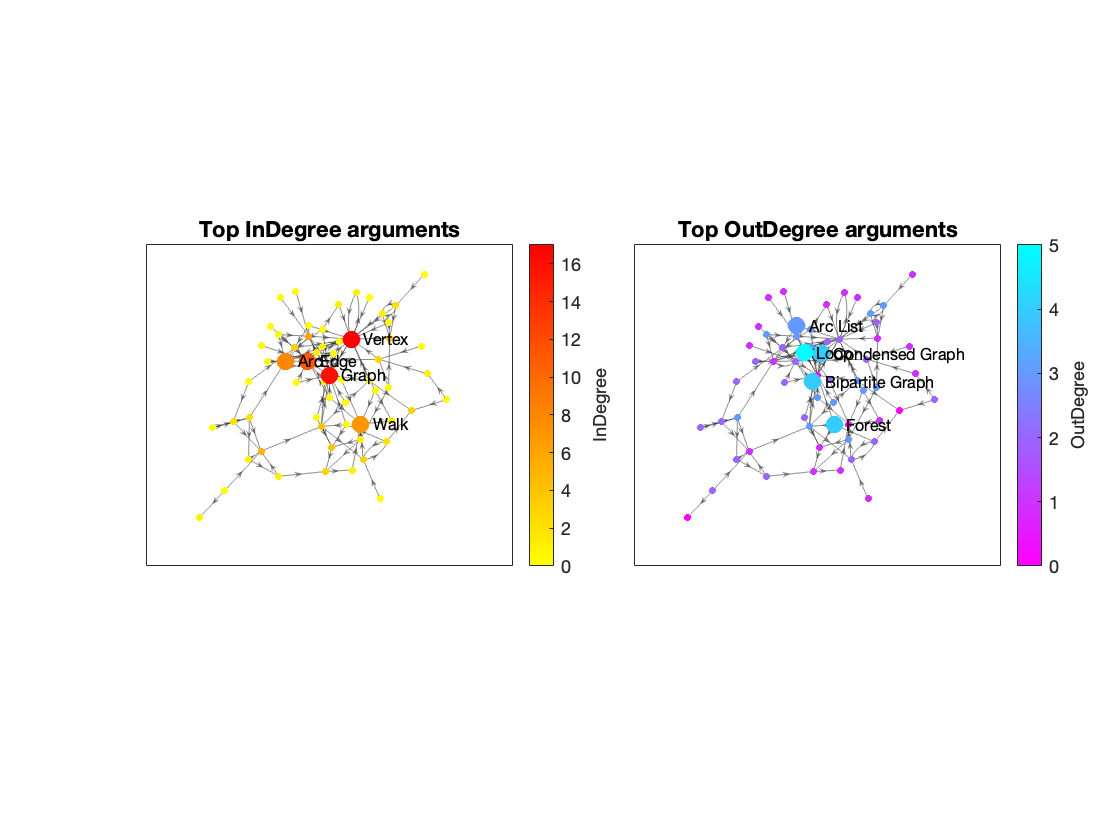

GB_names_length = length(word_B);
figure();
tiledlayout(1,2, 'TileSpacing', 'compact')
ax1 = nexttile;
top_indeg_names = strings(GB_names_length,1);
top_indeg_names(largest_indeg_index,1) = word_B(largest_indeg_index,1);
h1 = plot(GB,'NodeLabel', top_indeg_names, 'NodeCData', GB.Nodes.InDegree,'NodeLabelColor','k', 'Layout', 'Force', 'ArrowSize',3,'EdgeColor',[0.1,0.1,0.1],'MarkerSize',3);
highlight(h1, largest_indeg_index, 'MarkerSize',8);
cmap1 = colormap(ax1,flipud(autumn));
title('Top InDegree arguments');
c = colorbar;
c.Label.String = 'InDegree';
daspect([1 1 1])

ax2 = nexttile;
top_outdeg_names = strings(GB_names_length,1);
top_outdeg_names(largest_outdeg_index,1) = word_B(largest_outdeg_index,1);
h2 = plot(GB,'NodeLabel', top_outdeg_names, 'NodeCData', GB.Nodes.OutDegree,'NodeLabelColor','k', 'Layout', 'Force', 'ArrowSize',3,'EdgeColor',[0.1,0.1,0.1],'MarkerSize',3);
highlight(h2, largest_outdeg_index, 'MarkerSize',8);
cmap2 = colormap(ax2,flipud(cool));
title('Top OutDegree arguments');
c = colorbar;
c.Label.String = 'OutDegree';
daspect([1 1 1])

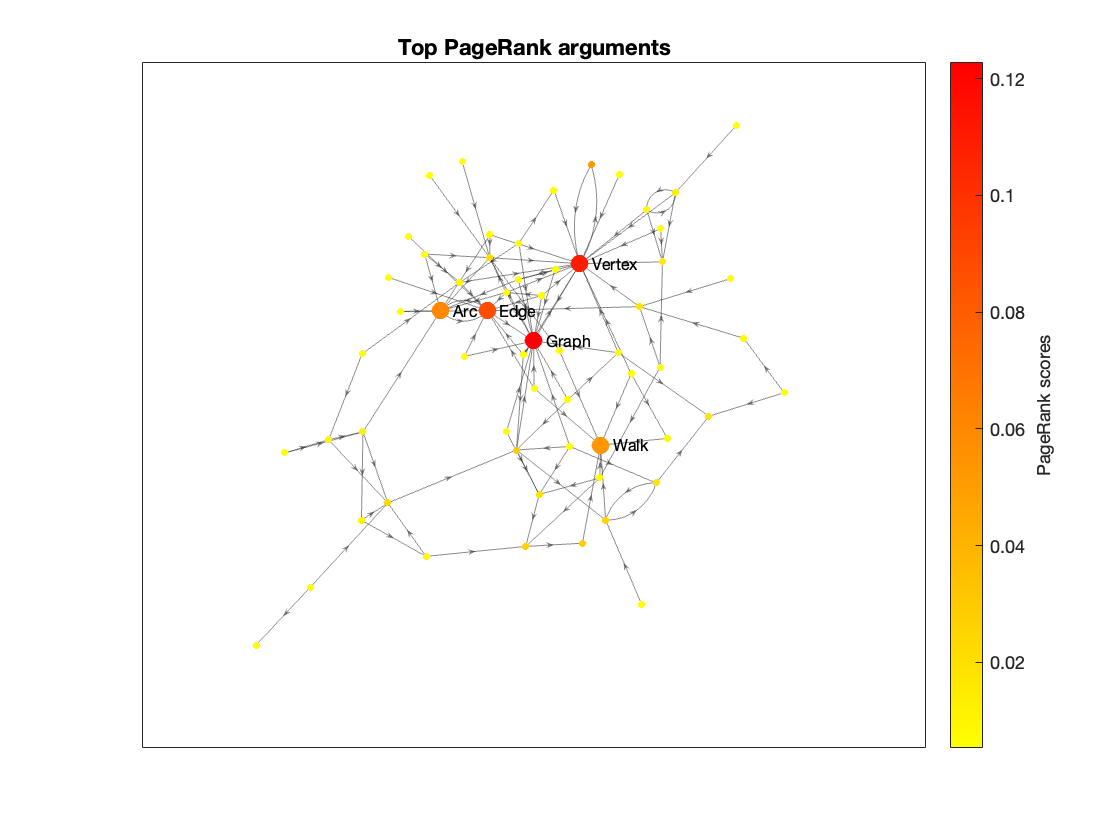

figure()
top_pagerank_names = strings(GB_names_length,1);
top_pagerank_names(largest_pagerank_index,1) = word_B(largest_pagerank_index,1);
h = plot(GB,'NodeLabel', top_pagerank_names, 'NodeCData', GB.Nodes.PageRank,'NodeLabelColor','k', 'Layout', 'Force', 'ArrowSize',3,'EdgeColor',[0.1,0.1,0.1],'MarkerSize',3);
highlight(h, largest_pagerank_index, 'MarkerSize',8);
colormap(flipud(autumn))
title('Top PageRank arguments');
c = colorbar;
c.Label.String = 'PageRank scores';
daspect([1 1 1])

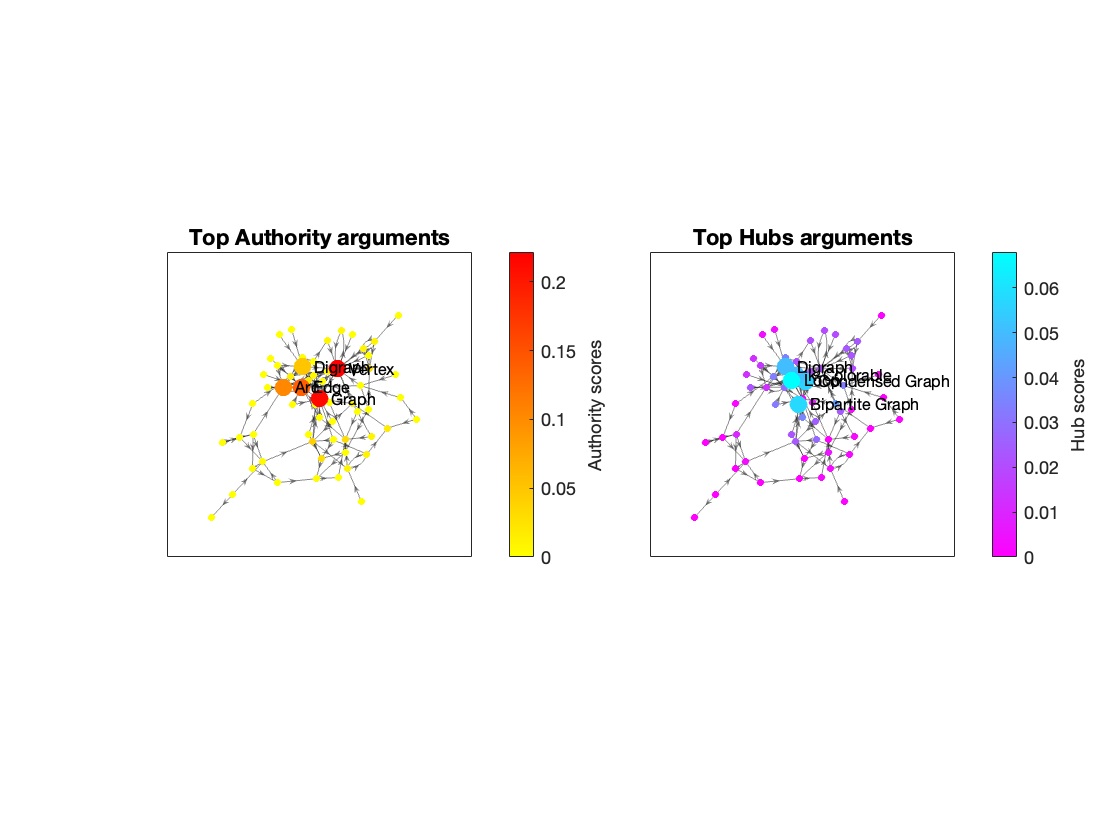

figure()
tiledlayout(1,2,'TileSpacing', 'compact')

ax2=nexttile;
top_auths_names = strings(GB_names_length,1);
top_auths_names(largest_auth_index,1) = word_B(largest_auth_index,1);
h = plot(GB,'NodeLabel', top_auths_names, 'NodeCData', GB.Nodes.Auth_matlab,'NodeLabelColor','k', 'Layout', 'Force', 'ArrowSize',3,'EdgeColor',[0.1,0.1,0.1],'MarkerSize',3);
highlight(h, largest_auth_index, 'MarkerSize',8);
colormap(ax2,flipud(autumn))
title('Top Authority arguments');
c = colorbar;
c.Label.String = 'Authority scores';
daspect([1 1 1])
ax1=nexttile;
top_hubs_names = strings(GB_names_length,1);
top_hubs_names(largest_hub_index,1) = word_B(largest_hub_index,1);
h = plot(GB,'NodeLabel', top_hubs_names, 'NodeCData', GB.Nodes.Hub_matlab,'NodeLabelColor','k', 'Layout', 'Force', 'ArrowSize',3,'EdgeColor',[0.1,0.1,0.1],'MarkerSize',3);
highlight(h, largest_hub_index, 'MarkerSize',8);
colormap(ax1,flipud(cool))
title('Top Hubs arguments');
c = colorbar;
c.Label.String = 'Hub scores';
daspect([1 1 1])

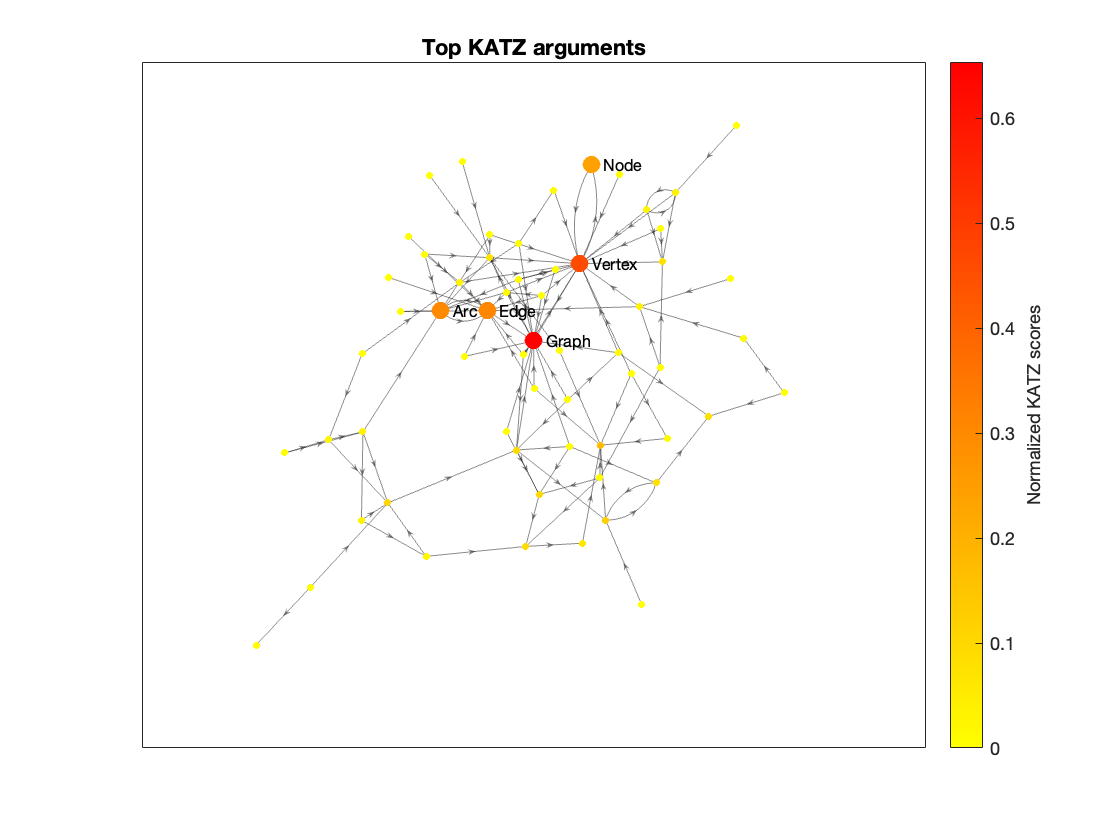

figure();
top_katz_names = strings(length(word_B),1);
top_katz_names(largest_katz_index,1) = word_B(largest_katz_index,1);
h = plot(GB,'NodeLabel', top_katz_names, 'NodeCData', GB.Nodes.KATZ,'NodeLabelColor','k', 'Layout', 'Force', 'ArrowSize',3,'EdgeColor',[0.1,0.1,0.1],'MarkerSize',3);
highlight(h, largest_katz_index, 'MarkerSize',8);
colormap(flipud(autumn))
title('Top KATZ arguments');
c = colorbar;
c.Label.String = 'Normalized KATZ scores';

daspect([1 1 1])

**Analisi Semantica**

L'analisi delle misure di centralità mostra che indici come PageRank, InDegree, Authority e Katz esprimono proprietà simili. In particolare, queste misure consentono di individuare i nodi più importanti della rete, ovvero quelli che in questo contesto sono gli argomenti fondamentali della teoria dei grafi, tra cui: Nodo, Arco, Lato, Vertice, Grafo, Grafo orientato e Cammino. Ciascun indice restituisce un ordine di "importanza" diverso per questi nodi, ma in questo contesto si può dire che i suddetti indici individuano quanto un argomento è fondamentale nella teoria dei grafi. Gli indici menzionati infatti, sono tutti basati su archi o percorsi "entranti", quindi i nodi con punteggi elevati sono argomenti "alla base" di molti altri argomenti della teoria dei grafi.

Le misure come OutDegree e Hub, invece, indicano chiaramente qualcosa di diverso. In particolare gli argomenti con score elevati per queste misure potrebbero essere quelli più complessi, in quanto "puntano" a molti altri argomenti o ad argomenti molto importanti. Dal momento in cui gli archi orientati rappresentano delle dipendenze, per cui se A punta B allora A dipende da B, gli argomenti individuati dalle misure di OutDegree e Hubs sono argomenti la cui comprensione dipende da molti altri argomenti, o da argomenti fondamentali nella teoria dei grafi.